Question 1 ) 


$$y=cos(2\pi f t)$$


f=1;
time_step=0.01;
fs=1/time_step;
t=0:time_step:2;
y=cos(2*pi*f*t);

plot:

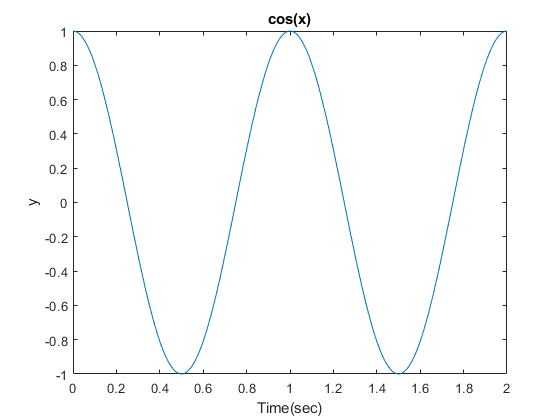

plot(t,y)
title cos(x)
ylabel y
xlabel Time(sec)

fourier transform :

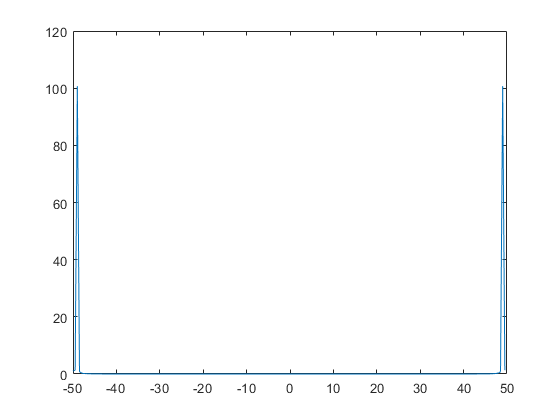

n= length(y);
fFft=(-n/2:n/2-1)*(fs/n);
yFft=fft(y);
yFftshift=fftshift(yFft);
plot(fFft,abs(yFft))

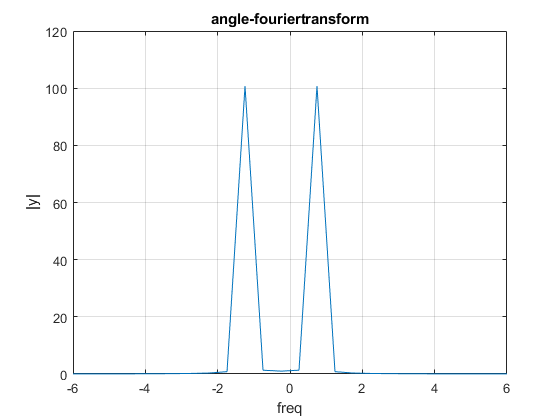

plot(fFft,abs(yFftshift))
title fouriertransform
xlim([-6,6])
xlabel("freq")
ylabel("|y|")
grid on
%agle for phase fourier transform
title angle-fouriertransform

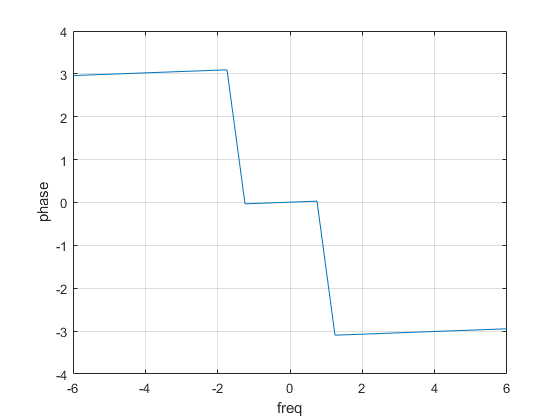

plot(fFft,angle(yFftshift))
xlim([-6,6])
ylabel("phase")
xlabel("freq")
grid on